numc = 1;
denc = [1 1];
t=[0:1:30];

[numz, denz] = c2dm(numc, denc, 0.1, 'zoh');
[num, den] = feedback(numz, denz, 1, 1)

num =          0    0.0952


den =     1.0000   -0.8097


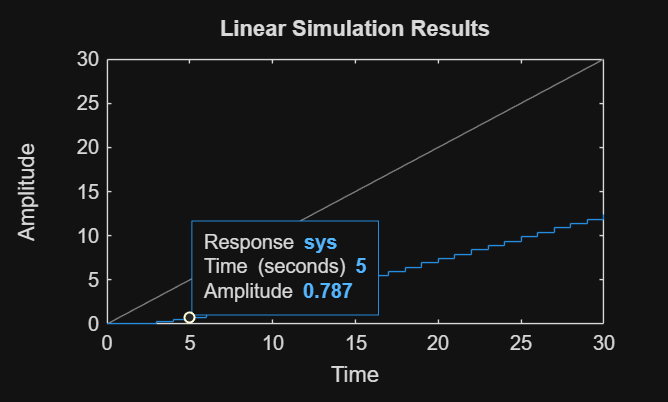

dlsim(num, den, t)

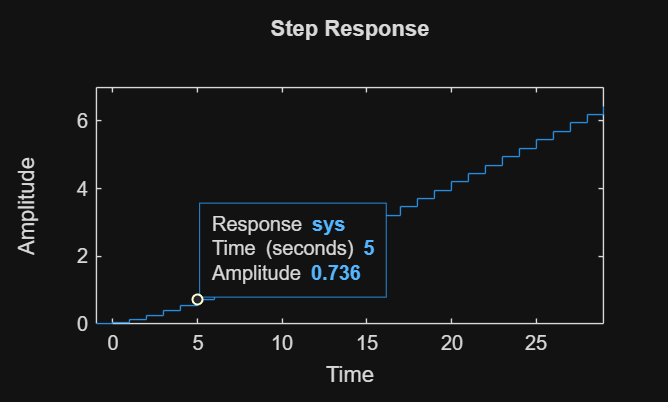

dstep(conv(num, [1 0]), conv(den, [1 -1]), t)